# CAB420 Machine Learning - Assignment 2 Report 

#### Student: Tran Quang Huy - n10069275

#### Student: Nathan Armishaw - n9157191

## Support Vector Machines

% Clear everything and turn off the warning 
clc; clear all; close all; 
warning('off','all'); 

% Load the datasets 
svm_data = load('data_ps3_2.mat'); 
% Training Data 
set1_train = svm_data.set1_train; % Set 1
set2_train = svm_data.set2_train; % Set 2
set3_train = svm_data.set3_train; % Set 3
set4_train = svm_data.set4_train; % Set 4

% Testing Data
set1_test = svm_data.set1_test; % Set 1
set2_test = svm_data.set2_test; % Set 2
set3_test = svm_data.set3_test; % Set 3
set4_test = svm_data.set4_test; % Set 4

### Part 1:

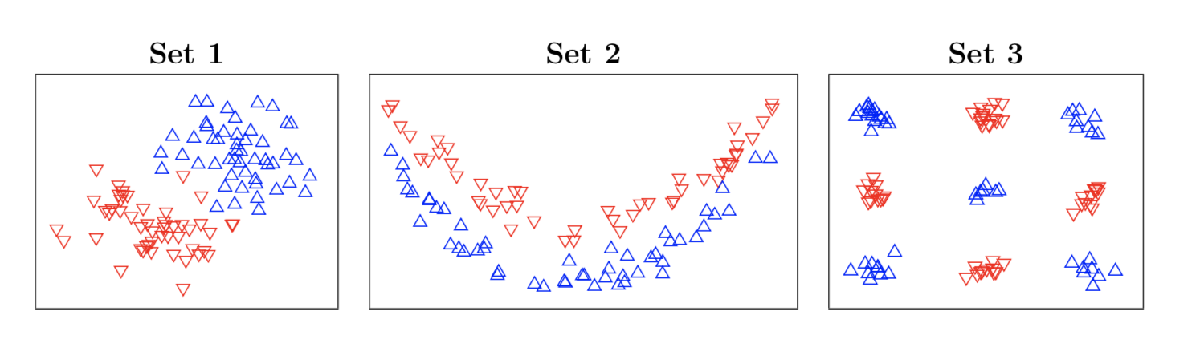

Figure 1: The 2-dimensional datasets of three sets 

From the figure above, it is considered that the best kernels for training SVM classifiers on first, second and third datasets are linear, polynomial and Gaussian kernels respectively. 

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

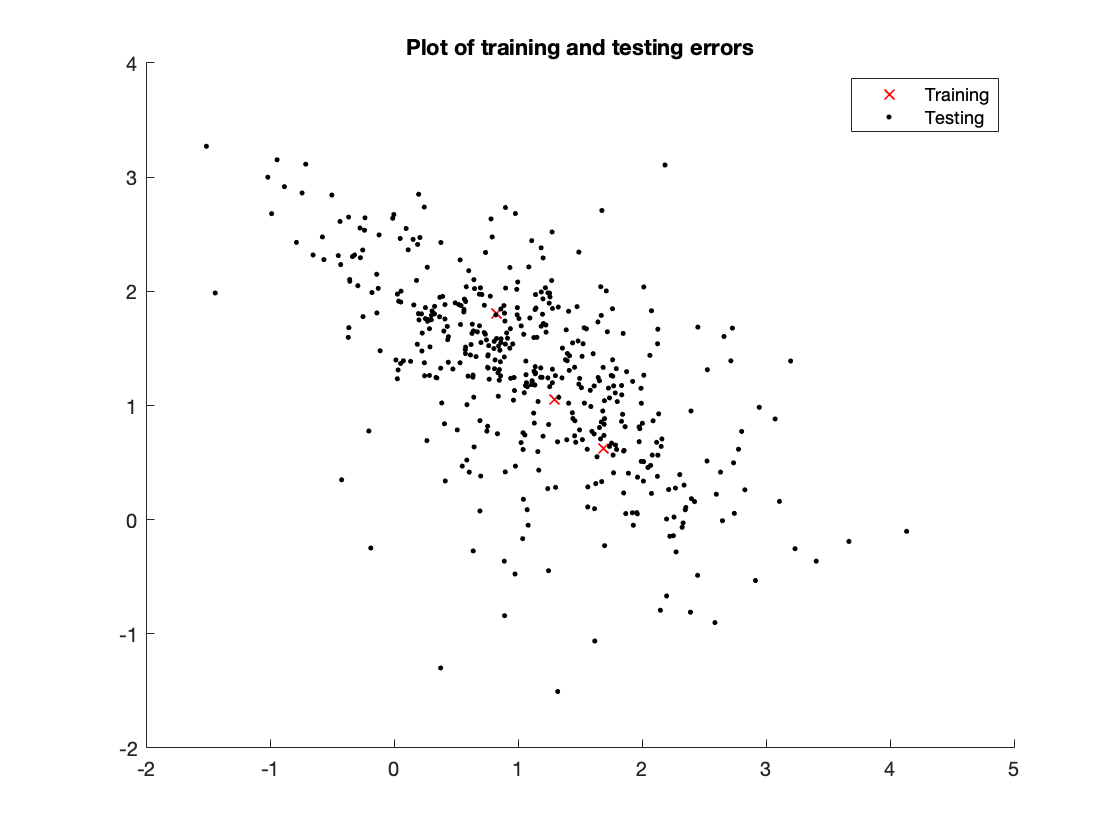

TEST RESULTS: 0.0446 of test examples were misclassified.


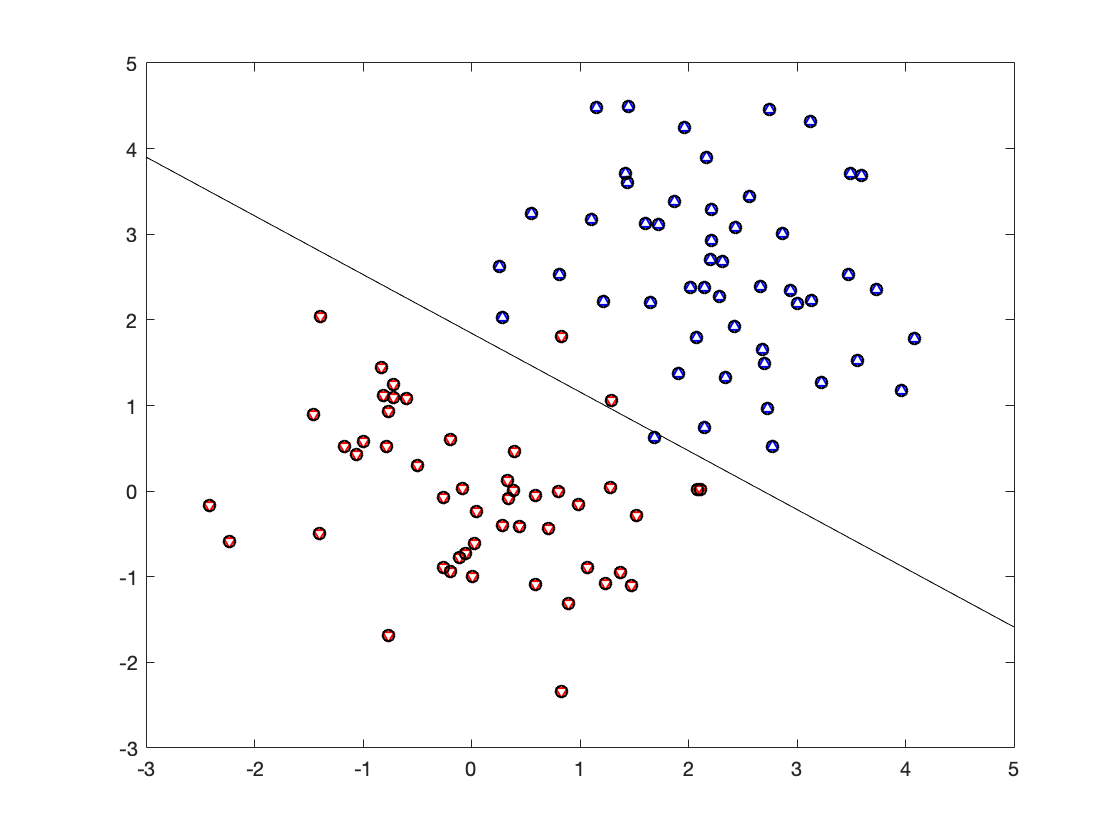

% For the first three datasets, consider the linear, second 
% order polynomial, Gaussian of standard deviation 1 kernels 
% Use C = 1000 for consistency 

% Use linear kernels for dataset 1  
svm_test(@Klinear,[],1000,set1_train,set1_test); 

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

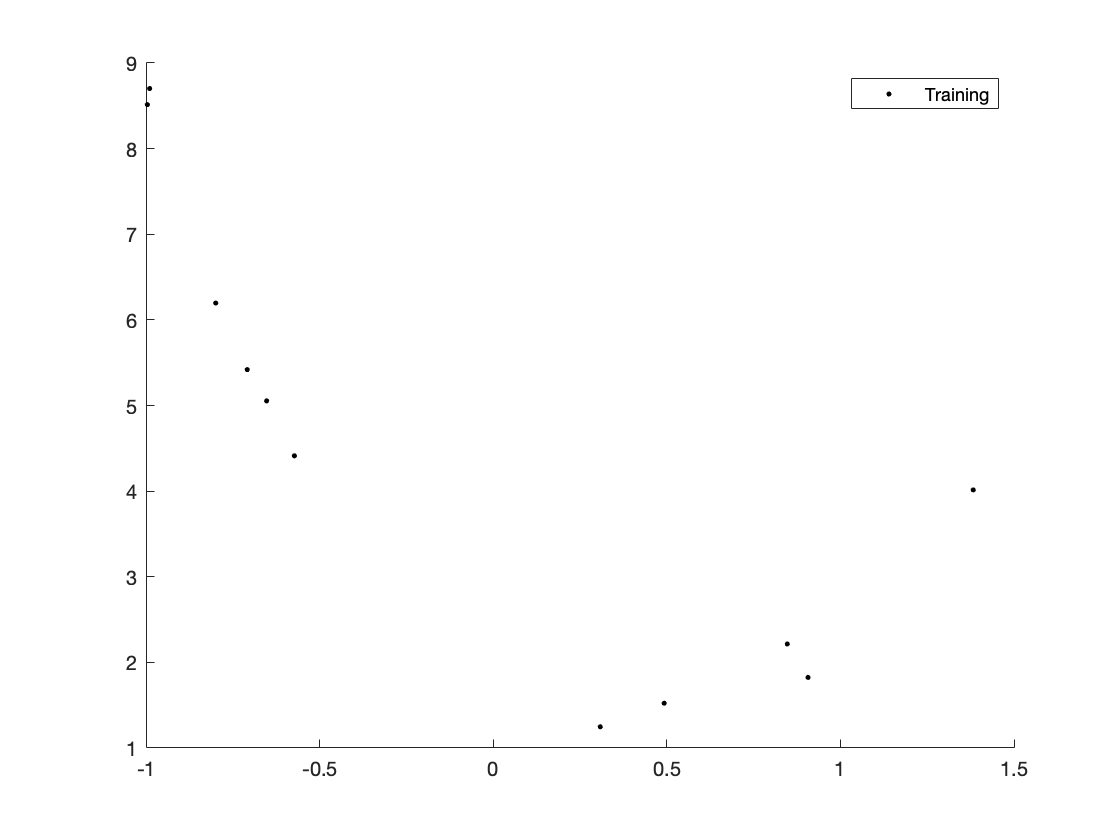

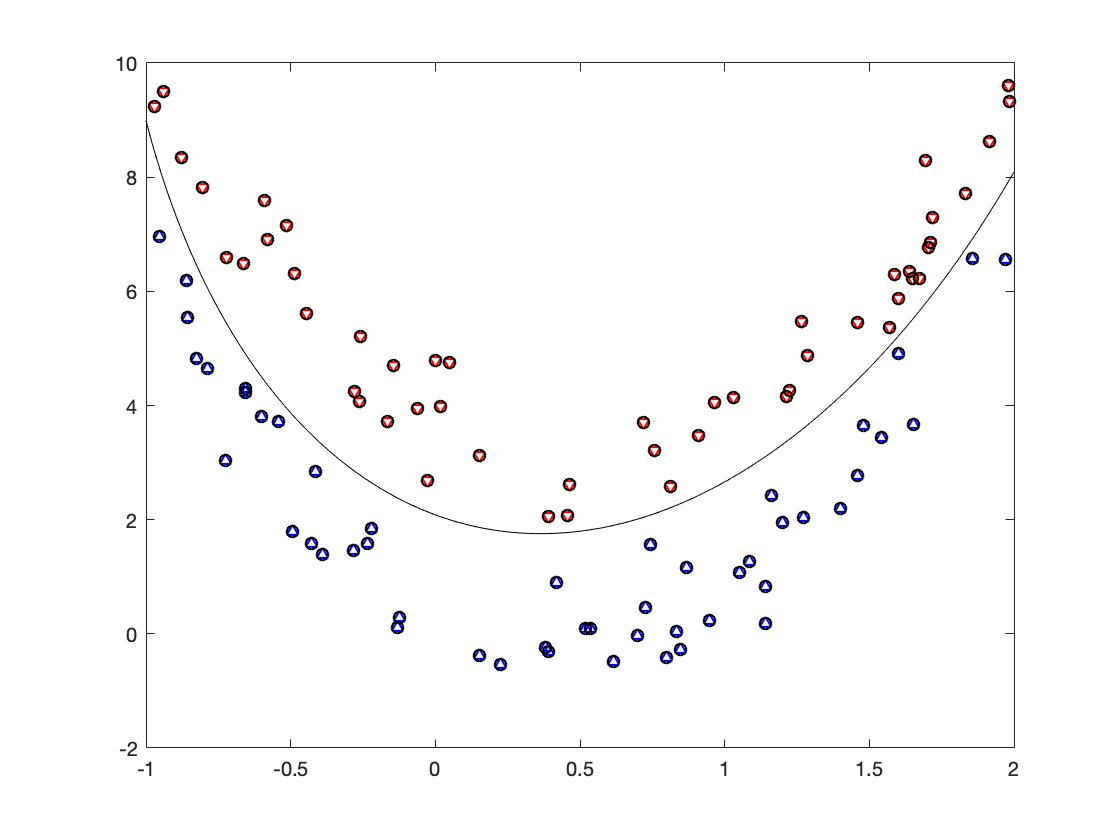

% Use second order kernels for dataset 2 
svm_test(@Kpoly,2,1000,set2_train,set2_test);  

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

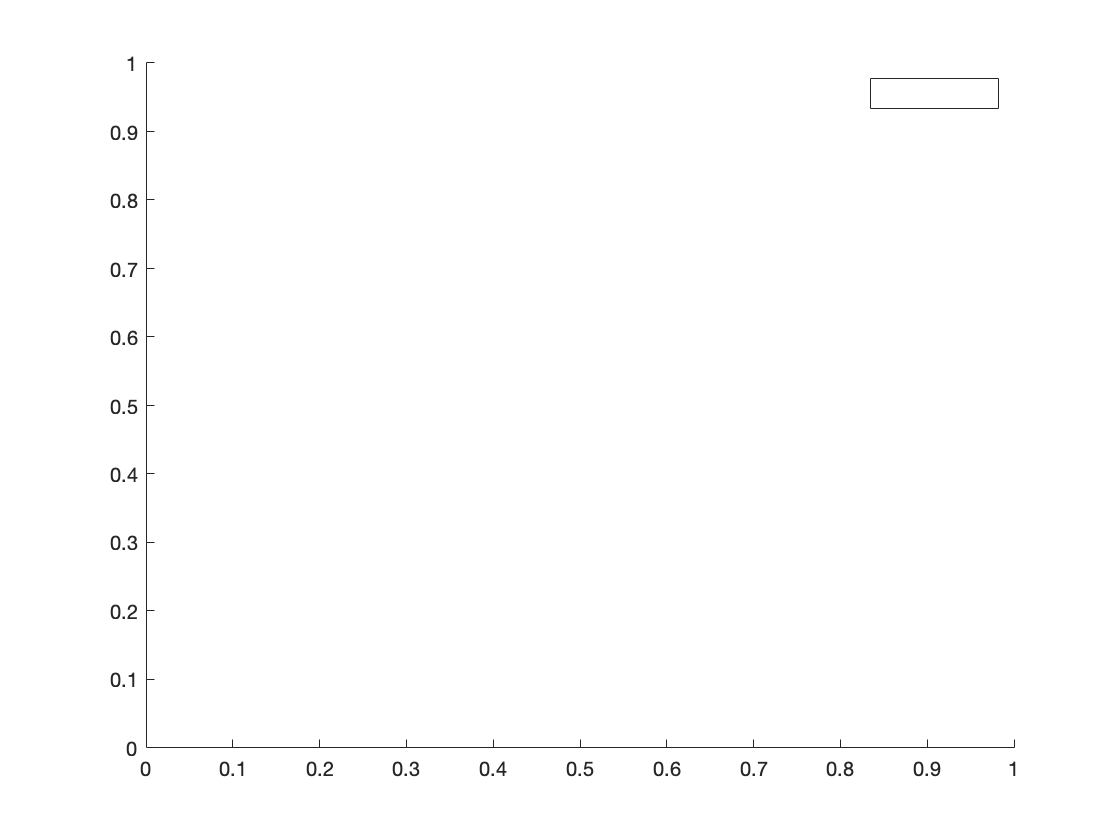

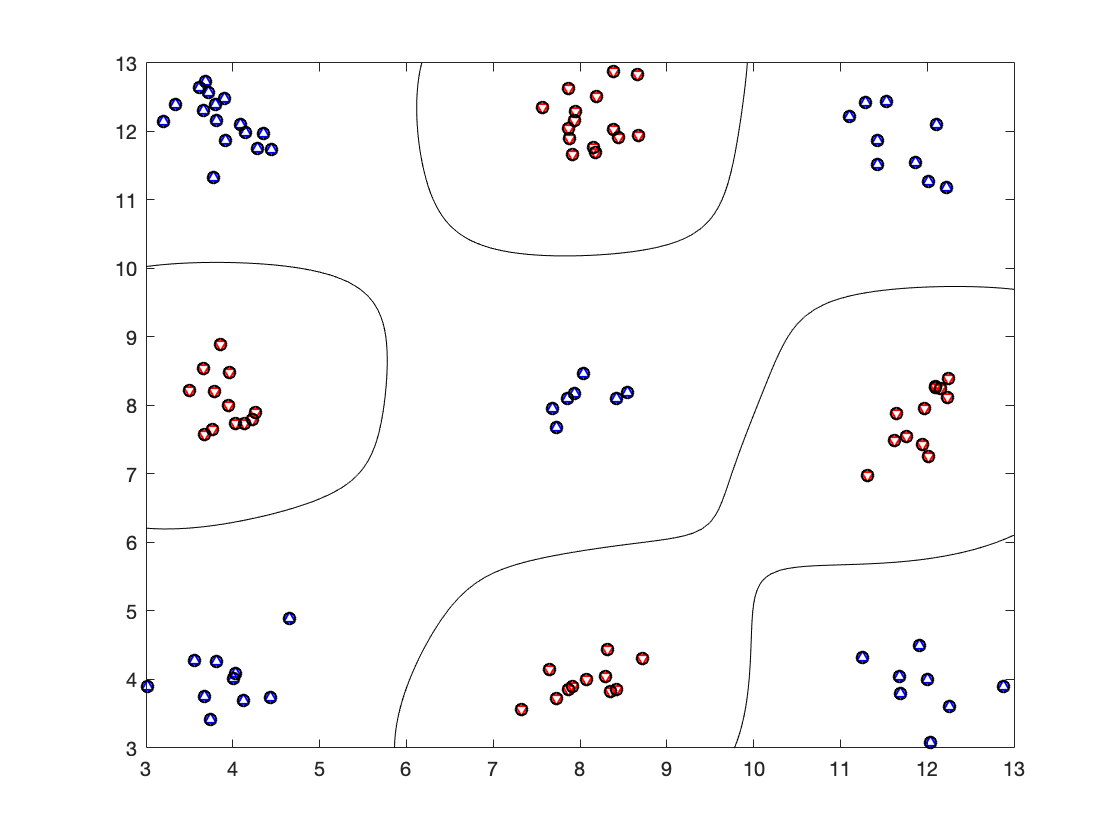

% Use Gaussian of standard deviation 1 kernels for dataset 3  
svm_test(@Kgaussian,1,1000,set3_train,set3_test);

### Part 2: 

TestError = zeros(3,1); % Initialize TestError variable 

% Train and test 4th dataset with a linear kernel
svm_linear4 = svm_train(set4_train,@Klinear,[],1000); % Training 

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

y_linear4 = sign(svm_discrim_func(set4_test.X,svm_linear4)); % Prediction 
errors_linear = find(y_linear4 ~= set4_test.y); % Testing Error  
TestError(1) = length(errors_linear)/length(set4_test.y); % Output the result 
fprintf('Linear SVM: %g of 4th test examples  were misclassified.\n',...
    length(errors_linear)/length(set4_test.y));

Linear SVM: 0.1375 of 4th test examples  were misclassified.


% Train and test 4th dataset with a polynomial of degree 2 kernel 
svm_poly4 = svm_train(set4_train,@Klinear,2,1000); % Training

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

y_poly4 = sign(svm_discrim_func(set4_test.X,svm_poly4)); % Prediction 
errors_poly = find(y_poly4 ~= set4_test.y); % Testing Error
TestError(2) = length(errors_poly)/length(set4_test.y);% Output the result 
fprintf('Polynomial SVM: %g of 4th test examples  were misclassified.\n',...
    length(errors_poly)/length(set4_test.y));

Polynomial SVM: 0.1375 of 4th test examples  were misclassified.


% Train and test 4th dataset with a Gaussian of standard deviation 1.5 kernels 
svm_gaussian4 = svm_train(set4_train,@Kgaussian,1.5,1000); % Training 

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

y_gaussian4 = sign(svm_discrim_func(set4_test.X,svm_gaussian4)); % Prediction 
errors_gaussian = find(y_gaussian4 ~= set4_test.y);  % Testing Error  
TestError(3) =  length(errors_gaussian)/length(set4_test.y); % Output the result 
fprintf('Gaussian SVM: %g of 4th test examples  were misclassified.\n',...
    length(errors_gaussian)/length(set4_test.y));

Gaussian SVM: 0.085 of 4th test examples  were misclassified.


Kernel = {'Linear';'Polynomial of degree 2';'Gaussian of std 1.5'}; 

% The test errors of 4th dataset trained on different kernels is as below: 
t = table(TestError,Kernel);
display(t);

t = 3×2 table
    TestError             Kernel         
    _________    ________________________

     0.1375      'Linear'                
     0.1375      'Polynomial of degree 2'
      0.085      'Gaussian of std 1.5'   
